# Lab 4: Time-frequency representations and Haar wavelets

## Haar wavelets on signals

### Question 4.1

Implement the Haar wavelet transform in the function dwlt_haar. Note that for other wavelets, this will not work as easily, hence, the explicit mention that it is for the haar wavelet.

This function should look something like this (Remember to save it in a seperate .m file)

and be in the same folder as this Matlab live script file. Then complete this code

x=[1 4 2 3 1 0 0 2]; %signal
c=[1/sqrt(2) 1/sqrt(2)];% todo; % low-pass
d=[1/sqrt(2) -1/sqrt(2)];% todo; % high-pass
[a,b] = dwlt_haar(x,c,d);
x*x' %signal energy

ans = 35

Also test your code witht he examples from the lectures. you may assume your signal is of even length.

### Question 4.2

Write the idwlt_haar function in this structure (Remember to save it in a seperate .m file)

Test it not just on the signal provided, but also on the ones from the lecture slides. Obviously, each signal you feed through dwlt_haar and idwlt_haar consecutively should be perfect reconstructed.

Some more test cases with signal s, approximation coefficients a and detail coefficients b to help you

s=[-4    -9    -8     6     4    -4     9    -9    -1    -2     5     6    -6     0    -1     3]

a=[-9.1924   -1.4142         0         0   -2.1213    7.7782   -4.2426    1.4142]

b=[-3.5355    9.8995   -5.6569  -12.7279   -0.7071    0.7071    4.2426    2.8284]

s=[4     5    -4     4     3    -7    -8     0     9    -3     2    -6     5    -5     0     4]

a=[6.3640         0   -2.8284   -5.6569    4.2426   -2.8284         0    2.8284]

b=[0.7071    5.6569   -7.0711    5.6569   -8.4853   -5.6569   -7.0711    2.8284]

s=[8     9     1    -7    -7    -5     7    -5     6    -5     9    -3    -6    -5     2    -1]

a=[12.0208   -4.2426   -8.4853    1.4142    0.7071    4.2426   -7.7782    0.7071]

b=[0.7071   -5.6569    1.4142   -8.4853   -7.7782   -8.4853    0.7071   -2.1213]

You can use the norm function to spot differences

 %testing Haar with other sigals
 %haar transform
 s = [-4 -9 -8 6 4 -4 9 -9 -1 -2 5 6 -6 0 -1 3];
 [a1,b1] = dwlt_haar(s,c,d)

a1 =    -9.1924   -1.4142         0         0   -2.1213    7.7782   -4.2426    1.4142


b1 =    -3.5355    9.8995   -5.6569  -12.7279   -0.7071    0.7071    4.2426    2.8284


 %haar inverse transform
 s_out = idwlt_haar(a1,b1,c,d)

s_out =    -4.0000   -9.0000   -8.0000    6.0000    4.0000   -4.0000    9.0000   -9.0000   -1.0000   -2.0000    5.0000    6.0000   -6.0000         0   -1.0000    3.0000


### Question 4.3

Finish the wldecom_haar function (Remember to save it in a seperate .m file)

And test it properly

 %from this signal we should get C=[ -28.6378 -1.7678 3.8891 3.1820 -25.0000 1.5000 1.5000 -48.0000 -4.2426 21.2132 37.4767 14.1421 12.0208 15.5563 13.4350 -27.5772 31.1127]
 % with N = 3
 
 s = [4 -2 -39 -9 -36 17 -18 2 -11 6 -12 10 15 34 -4 -43 -17 27];
 N = 3;
 
 C = wldecom_haar(s,N,c,d)

C =   -28.6378   -1.7678    3.8891    3.1820  -25.0000    1.5000    1.5000  -48.0000   -4.2426   21.2132   37.4767   14.1421   12.0208   15.5563   13.4350  -27.5772   31.1127


## Haar Wavelets on images

### Question 4.4

Implement a dwlt2_haar function starting with the structure

Probably it is wise to also call dwlt_haar from here (hint)

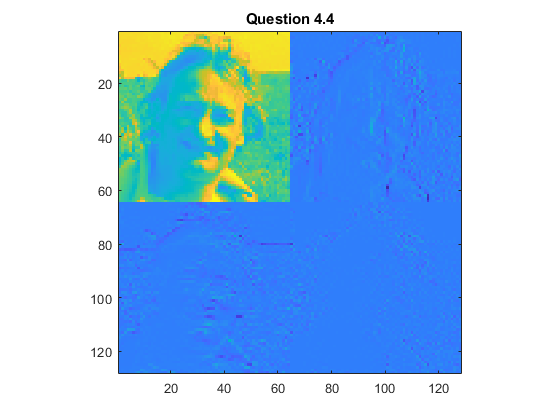

load ronald
[B,H,V,D] = dwlt2_haar(ronald,c,d);
figure;imagesc([B V;H D]);axis image
title('Question 4.4')

### Question 4.5

Iterate the 2D composition using dwlt2_haar below

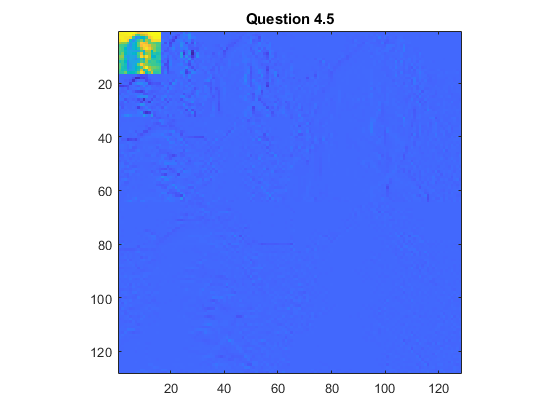

%At each iteration we only take the B and repass through Haar transform and
%just add this to the image in the new quadrant (line 17)
N=3;
B = ronald;
for i = 1:N
    [B,H,V,D] = dwlt2_haar(B,c,d);
    Im(1:size(B,1)+size(V,1),1:size(B,2)+size(H,1)) = [B V;H D];
end

figure;imagesc(Im);axis image
title('Question 4.5')

## Haar wavelets and edge detection

### Question 4.6

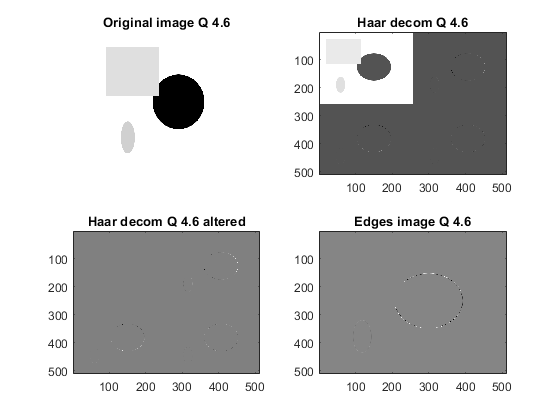

im_foo = double(imread('foo.png'));
[B1,H1,V1,D1] = dwlt2_haar(im_foo,c,d);
B1r = zeros(size(B1,1),size(B1,2));
recons = idwlt2_haar(B1r,H1,V1,D1,c,d);
% finish it
figure();
subplot(2,2,1)
imagesc(im_foo);
axis image off
colormap gray
title('Original image Q 4.6')
subplot(2,2,2);
imagesc([B1 V1;H1 D1])
title('Haar decom Q 4.6')
subplot(2,2,3);
imagesc([B1r V1;H1 D1])
title('Haar decom Q 4.6 altered')
subplot(2,2,4)
imagesc(recons)
title('Edges image Q 4.6')

### Question 4.7

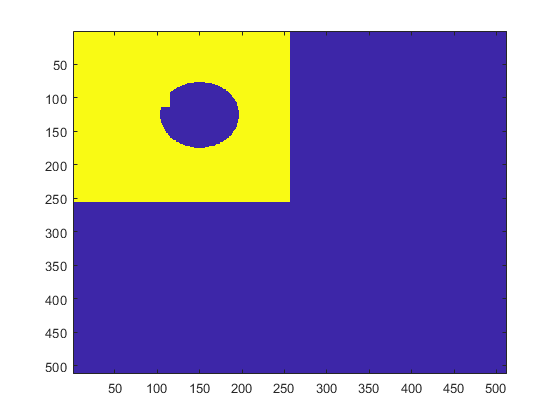

%Thresholding
low = 200;
high = 100;
im = im_foo;
inter = not((low<im_foo)&(im_foo<high));

thresImg = ((255.*inter).*im)./im;

figure()
%colormap gray
[B2,H2,V2,D2] = dwlt2_haar(thresImg,c,d);
B2r = zeros(size(B2,1),size(B2,2));
recons2 = idwlt2_haar(B2,H2,V2,D2,c,d);
image([B2 V2;H2 D2])

### Question 4.8

% todo

## Short term Fourier transforms

### Question 4.9

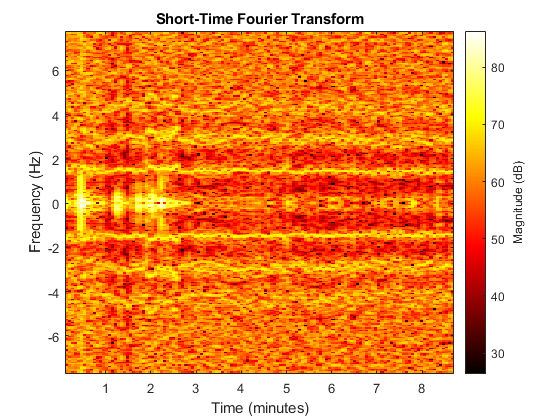

load data2_1
fs=15.5;
win = hamming(250,"periodic");
stft(x,fs,"Window",win)
colormap("hot")

### Question 4.10 and 4.11

figure;
s1=subplot(2,1,1)
% todo time signal
s2=subplot(2,1,2)
% todo spectrogram
linkaxes([s1, s2], 'x');